% Encabezado...
disp('-----------------------------------------------');

-----------------------------------------------


disp('PRACTICA 02. FUNDAMENTOS DE MATLAB');

PRACTICA 02. FUNDAMENTOS DE MATLAB


disp('-----------------------------------------------');

-----------------------------------------------


disp('  Nombre: Fernando Huilca');

  Nombre: Fernando Huilca


disp('  Fecha: 06/01/2024');

  Fecha: 06/01/2024


disp('  Profesor: Andrés Larco');

  Profesor: Andrés Larco


disp('-----------------------------------------------');

-----------------------------------------------



% Aquí comienza el código de la práctica...

## Funciones básicas de Plot

### Creating a Plot

La función `plot` tiene diferentes formas, según los argumentos de entrada.

• Si `y` es un vector, `plot(y) `produce una gráfica lineal por partes de los elementos de `y vs `el índice de los elementos de `y`.

• Si especifica dos vectores como argumentos, `plot(x,y) `produce una gráfica de `y` vs `x`.

x = 0:pi/100:2*pi;
y = sin(x);
plot(x,y)

Agregue etiquetas de eje y un título. Los caracteres \pi en la función `xlabel `crean el símbolo `π`. La propiedad `FontSize` en la función `title` aumenta el tamaño del texto utilizado para el título.

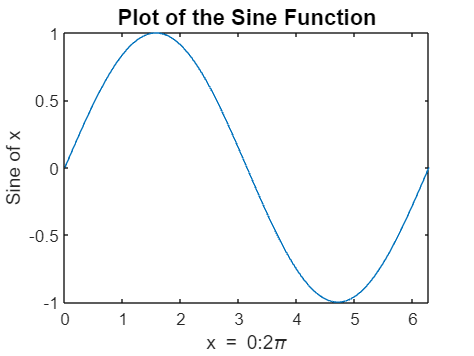

xlabel('x = 0:2\pi')
ylabel('Sine of x')
title('Plot of the Sine Function','FontSize',12)

### Plotting Multiple Data Sets in One Graph

Trazar múltiples conjuntos de datos en un gráficoMúltiples argumentos de pares x-y crean múltiples gráficos con una sola llamada para trazar. MATLAB utiliza un color diferente para cada línea. 

Por ejemplo, estas declaraciones trazan tres funciones relacionadas de x:

x = 0:pi/100:2*pi;
y = sin(x);
y2 = sin(x-.25);
y3 = sin(x-.5);
plot(x,y,x,y2,x,y3)

La función `legend` proporciona una manera sencilla de identificar las líneas individuales:

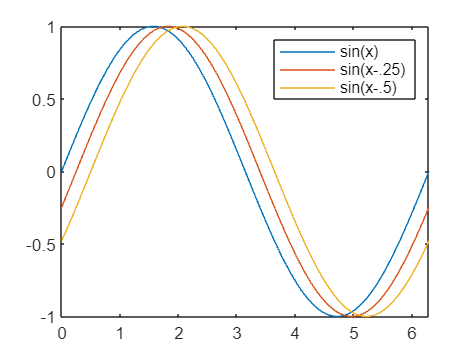

legend('sin(x)','sin(x-.25)','sin(x-.5)')

### Specifying Line Styles and Colors

Es posible especificar el color, estilos de línea y marcadores (como signos de suma o círculos) al trazar tus datos utilizando el comando plot:

plot(x, y, 'color_estilo_marcador')

Donde `color_estilo_marcador` contiene de uno a cuatro caracteres (encerrados en comillas simples) construidos a partir de un color, un estilo de línea y un tipo de marcador. Por ejemplo:

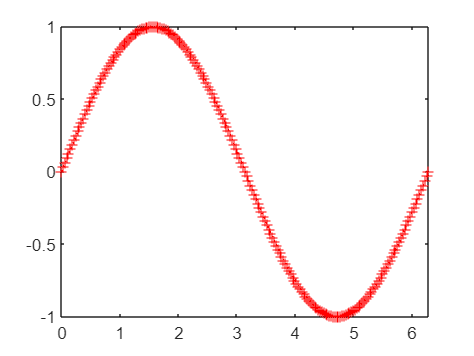

plot(x, y, 'r:+')

Grafica los datos utilizando una línea punteada roja y coloca un marcador + en cada punto de datos. `color_estilo_marcador` se compone de combinaciones de los siguientes elementos.

## **Graficando Líneas y Marcadores**

Si especificas un tipo de marcador pero no un estilo de línea, MATLAB crea el gráfico utilizando solo marcadores, sin línea. Por ejemplo,

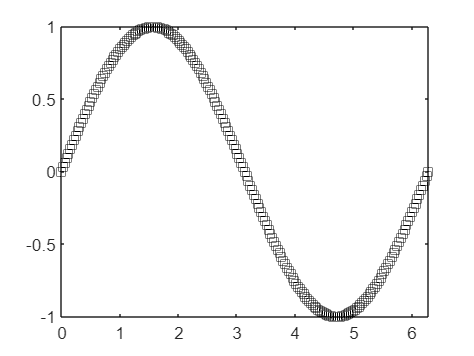

plot(x, y, 'ks')

La siguiente declaración traza una línea de puntos rojos y coloca marcadores de signo más en cada punto de datos:

plot(x,y,'r:+')

### Colocar Marcadores en Cada Décimo Punto de Datos

Este ejemplo muestra cómo utilizar menos puntos de datos para graficar los marcadores que los que se utilizan para graficar las líneas. Este ejemplo grafica los datos dos veces utilizando un número diferente de puntos para las líneas punteadas y las gráficas de marcadores.

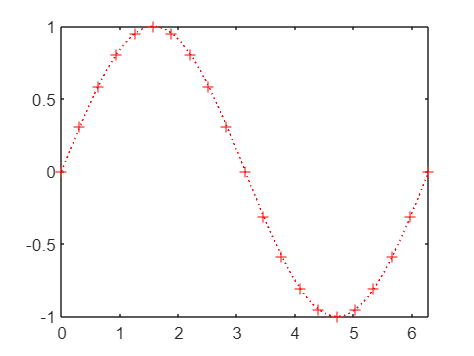

x1 = 0:pi/100:2*pi;
x2 = 0:pi/10:2*pi;
plot(x1, sin(x1), 'r:', x2, sin(x2), 'r+')

### Gráficos de Datos Imaginarios y Complejos 

Cuando pasas valores complejos como argumentos a la función `plot` en MATLAB, la parte imaginaria se ignora, excepto cuando pasas un solo argumento complejo. En este caso especial, el comando es un atajo para un gráfico de la parte imaginaria frente a la parte real. Por lo tanto,

`plot(Z) `

donde `Z `es un vector o matriz complejo, equivale a

`plot(real(Z),imag(Z)) `

Las siguientes instrucciones dibujan un polígono de 20 lados con pequeños círculos en los vértices.

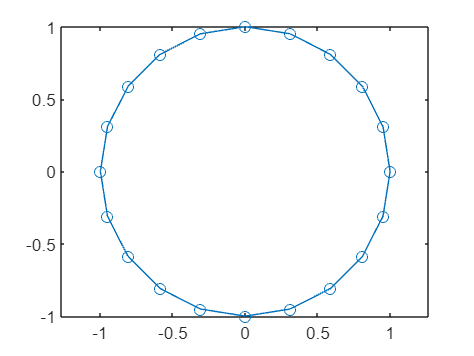

t = 0:pi/10:2*pi;
plot(exp(1i*t),'-o')
axis equal

El comando `axis equal` hace que los incrementos individuales de las marcas en los ejes x e y tengan la misma longitud, lo que hace que este gráfico tenga una apariencia más circular.

### Añadir Gráficos a un Gráfico Existente

El comando `hold` te permite añadir gráficos a un gráfico existente en MATLAB. Cuando escribes:

`hold on`

MATLAB no reemplaza el gráfico existente cuando emites otro comando de trazado. En cambio, MATLAB combina el nuevo gráfico con el gráfico actual.

Por ejemplo, estas instrucciones primero crean un gráfico de superficie de la función `peaks` y luego superponen un gráfico de contorno de la misma función.

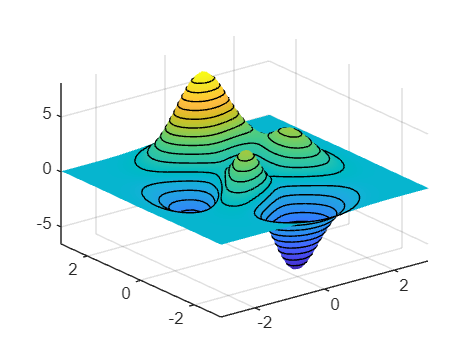

[x,y,z] = peaks;
% Create surface plot
surf(x,y,z)
% Remove edge lines a smooth colors
shading interp
% Hold the current graph
hold on
% Add the contour graph to the pcolor graph
contour3(x,y,z,20,'k')
% Return to default
hold off

### Ventana de Figuras

Las funciones de trazado abren automáticamente una nueva ventana de figura si no hay ventanas de figura creadas previamente. Si hay múltiples ventanas de figura abiertas, MATLAB utiliza la que está designada como la "figura actual", generalmente la última utilizada.

Para hacer que una ventana de figura existente sea la figura actual, puedes hacer clic en la ventana con el ratón o puedes escribir:

figure(n)

donde` n` es el número en la barra de título de la figura.

Para abrir una nueva ventana de figura y convertirla en la figura actual, escribir:

figure

### Mostrar Múltiples Gráficos en una Sola Figura

El comando `subplot` te permite mostrar varios gráficos en la misma ventana o imprimirlos en la misma hoja de papel. Al escribir:

`subplot(m,n,p)`

se divide la ventana de la figura en una matriz m-por-n de subgráficos pequeños y se selecciona el p-ésimo subgráfico para el gráfico actual. Los gráficos se numeran a lo largo de la primera fila de la ventana de la figura, luego la segunda fila y así sucesivamente. Por ejemplo, estas declaraciones grafican datos en tres subregiones de la ventana de la figura.

% x = 0:pi/20:2*pi;
% subplot(3,1,1); plot(sin(x))
% subplot(3,1,2); plot(cos(x))
% subplot(3,1,3); plot(sin(x).*cos(x))

### Controlling the Axes

El comando `axes` proporciona una serie de opciones para configurar la escala, la orientación y la relación de aspecto de los gráficos.

### Automatic Axis Limits and Tick Marks

De forma predeterminada, MATLAB encuentra los máximos y mínimos de los datos y elige los límites de los ejes para abarcar este rango. MATLAB selecciona los límites y los valores de las marcas de eje para producir un gráfico que muestra claramente los datos. Sin embargo, puede establecer sus propios límites utilizando las funciones `axis` o `xlim`,` ylim `y `zlim`.

### Setting Axis Limits

El comando `axis` permite especificar sus propios límites:

`axis([xmin xmax ymin ymax])`

o para gráficos tridimensionales:

`axis([xmin xmax ymin ymax zmin zmax])`

Con el siguiente comando se habilita la selección automática de límites nuevamente:

`axis auto`

### Setting the Axis Aspect Ratio

El comando de eje también permite especificar una serie de modos predefinidos. Por ejemplo:

`axis square`

hace que el eje `x` y el eje `y` tengan la misma longitud.

`axis equal`

hace que los incrementos de las marcas individuales en los ejes `x` e `y` tengan la misma longitud. Esto significa:

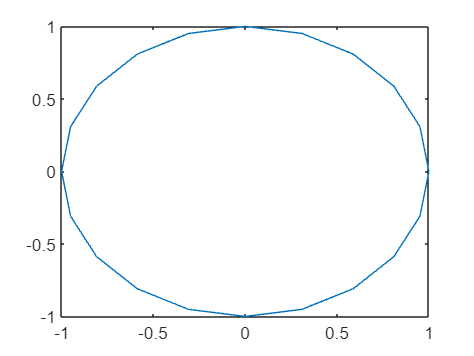

plot(exp(1i*(0:pi/10:2*pi)))

seguido de `axis square` o `axis equal `convierte el óvalo en un círculo propio:

`axis auto normal`

devuelve la escala del eje a su modo automático predeterminado.

### Configuraciones de visualizacion Axis 

Puede utilizar el comando `axis` para hacer que el eje sea visible o invisible.

`axis on`

hace visibles los ejes. Este es el valor predeterminado.

`axis off`

hace que los ejes sean invisibles.

### Setting Grid Lines 

El comando `grid` activa y desactiva las líneas de la cuadrícula. La declaración:

`grid on`

activa las líneas de la cuadrícula y

`grid off`

las vuelve a desactivar.

### **Agregar Etiquetas a los Ejes y Títulos**

Este ejemplo muestra cómo crear un gráfico y mejorar su presentación:

- Define los límites de los ejes x e y (axis).

- Etiqueta los ejes x e y (xlabel, ylabel).

- Agrega un título (title).

- Añade una nota de texto en el gráfico (text).

- Utiliza la notación LaTeX para producir símbolos matemáticos.

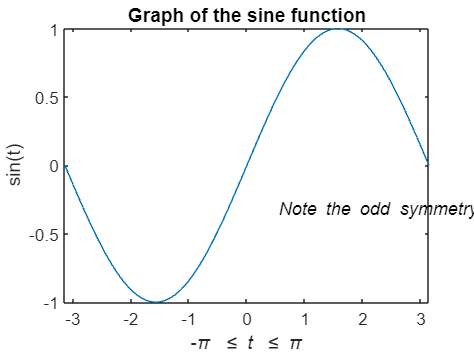

t = -pi:pi/100:pi;
y = sin(t);
plot(t,y)
axis([-pi pi -1 1])
xlabel('-\pi \leq {\itt} \leq \pi')
ylabel('sin(t)')
title('Graph of the sine function')
text(0.5,-1/3,'{\itNote the odd symmetry.}')

### Guardar Figuras

Para guardar una figura, selecciona "Guardar" en el menú Archivo. Esto escribe la figura en un archivo, incluyendo datos de propiedades, menús, controles de usuario y todas las anotaciones (es decir, toda la ventana). Si no has guardado la figura antes, se muestra el cuadro de diálogo "Guardar como". Este cuadro de diálogo proporciona opciones para guardar la figura como un archivo .fig o exportarla a un formato gráfico.

Si ya has guardado la figura previamente, al usar "Guardar" nuevamente, la figura se guarda "silenciosamente", sin mostrar el cuadro de diálogo "Guardar como".

Para guardar una figura en un formato gráfico estándar para su uso con otras aplicaciones, como TIFF o JPG, selecciona "Guardar como" (o "Configuración de exportación", si deseas más control) desde el menú Archivo.

Nota: Cada vez que especificas un formato para guardar una figura, ese formato se utilizará la próxima vez que guardes esa figura o una nueva. Si no quieres guardar en el formato utilizado anteriormente, utiliza "Guardar como" y asegúrate de establecer el tipo de archivo en el menú desplegable según el tipo de archivo que deseas escribir.

También puedes guardar desde la línea de comandos:

- Usa la función `savefig` para guardar una figura y los objetos gráficos que contiene como un archivo .fig.

- Utiliza el comando `saveas`, incluyendo opciones, para guardar la figura en diversos formatos.

### Cargar una figura 

Puedes cargar figuras en MATLAB utilizando estas funciones:

- Usa la función `openfig` para cargar figuras guardadas como archivos .fig.

- Emplea la función `imread` para leer archivos gráficos estándar (incluidas las figuras guardadas) en MATLAB.

### Generar Código MATLAB para Recrear una Figura

Puedes generar código MATLAB que recrea una figura y el gráfico que contiene seleccionando "Generar código" desde el menú Archivo de la figura. Esta opción es especialmente útil si has desarrollado un gráfico utilizando herramientas de trazado y deseas crear un gráfico similar utilizando los mismos o diferentes datos.

### Guardar Datos en el espacio de trabajo

Puede guardar las variables en su espacio de trabajo seleccionando **Save Workspace As** en el menú **File** de la figura. Puede recargar los datos guardados utilizando el elemento **Import Data **en el menú **File** de la figura. MATLAB admite una variedad de formatos de archivos de datos, incluidos archivos de datos MATLAB, que tienen una extensión `.mat.`

### Creación de Gráficos de Malla y Superficie

#### Acerca de los Gráficos de Malla y Superficie

MATLAB define una superficie mediante las coordenadas z de puntos sobre una cuadrícula en el plano x-y, utilizando líneas rectas para conectar puntos adyacentes. Las funciones `mesh` y `surf` muestran superficies en tres dimensiones.

- `mesh` produce superficies de alambre que colorean solo las líneas que conectan los puntos definitorios.

- `surf` muestra tanto las líneas que conectan como las caras de la superficie en color.

MATLAB colorea las superficies asignando valores de datos z a índices en el mapa de colores de la figura.

Visualización de Funciones de Dos Variables

Para mostrar una función de dos variables, z = f(x, y):

- Genera matrices X e Y que consistan en filas y columnas repetidas, respectivamente, sobre el dominio de la función.

- Utiliza X e Y para evaluar y graficar la función.

La función `meshgrid` transforma el dominio especificado por un solo vector o dos vectores x e y en matrices X e Y para su uso en la evaluación de funciones de dos variables. Las filas de X son copias del vector x y las columnas de Y son copias del vector y.

### Gráfica de la Función sinc

Este ejemplo muestra cómo evaluar y graficar la función sinc bidimensional, sin(R)/R, entre las direcciones x e y. R es la distancia desde el origen, que está en el centro de la matriz. Agregar `eps` (un valor muy pequeño) evita un agujero en la malla en el punto donde R = 0.

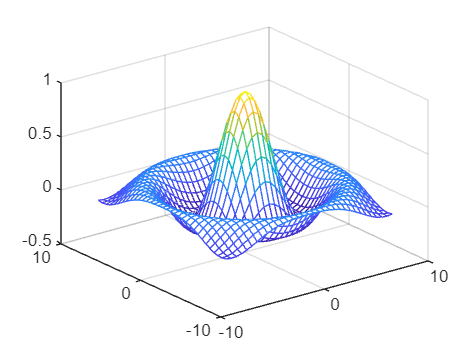

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
mesh(X,Y,Z)

De forma predeterminada, MATLAB utiliza el mapa de colores actual para colorear la malla.

### Gráficos de Superficie a Color

Este ejemplo muestra cómo graficar la función sinc como un gráfico de superficie, especificar un mapa de colores y agregar una barra de colores para mostrar la asignación de datos a color.

Un gráfico de superficie es similar a un gráfico de malla, excepto que las caras rectangulares de la superficie están coloreadas. El color de cada cara se determina por los valores de Z y el mapa de colores (un mapa de colores es una lista ordenada de colores).

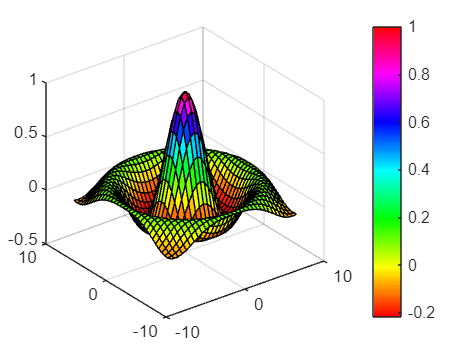

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
surf(X,Y,Z)
colormap hsv
colorbar

### Haciendo Superficies Transparentes

Este ejemplo muestra cómo puedes hacer que las caras de una superficie sean transparentes en diversos grados. La transparencia (llamada valor alfa) se puede especificar para todo el objeto o puede basarse en un `alphamap`, que se comporta de manera similar a los mapas de colores.

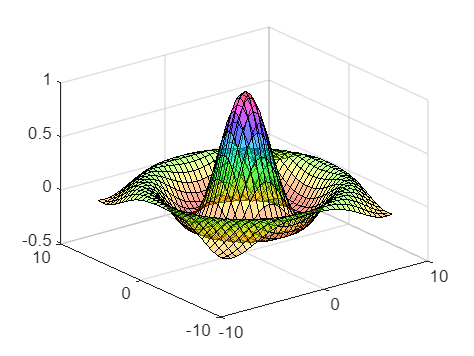

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
surf(X,Y,Z)
colormap hsv
alpha(.4)

### Iluminación de Gráficos de Superficie con Luces

Este ejemplo muestra la misma superficie que los ejemplos anteriores, pero la colorea de rojo y elimina las líneas de malla. Luego, se agrega un objeto de luz a la izquierda de la "cámara" (la cámara es la ubicación en el espacio desde donde estás viendo la superficie).

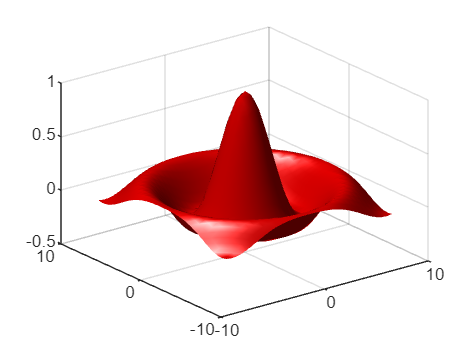

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
surf(X,Y,Z,'FaceColor','red','EdgeColor','none')
camlight left;
lighting phong

**Iluminación** es la técnica de iluminar un objeto con una fuente de luz direccional. En ciertos casos, esta técnica puede hacer que las diferencias sutiles en la forma de la superficie sean más fáciles de ver. La iluminación también se puede usar para agregar realismo a los gráficos tridimensionales.

### Manipulación de la Superficie

La barra de herramientas de la figura y la barra de herramientas de la cámara proporcionan formas de explorar gráficos tridimensionales de manera interactiva. Muestra la barra de herramientas de la cámara seleccionando **"Camera Toolbar"** desde el menú de vista de la figura.

Estas herramientas te permiten mover la cámara alrededor del objeto de superficie, hacer zoom, agregar iluminación y realizar otras operaciones de visualización sin necesidad de emitir comandos.

## Mostrar Imágenes

#### Datos de Imágenes

Puedes mostrar una matriz numérica 2-D como una imagen. En las imágenes, los elementos de la matriz determinan la luminosidad o el color de las imágenes. Por ejemplo, carga una matriz de imagen y su mapa de colores:

load durer
whos

  Name               Size               Bytes  Class                                   Attributes

  A                  1x5                   40  double                                            
  B                  1x5                   40  double                                            
  R                 33x33                8712  double                                            
  X                648x509            2638656  double                                            
  Y                 33x33                8712  double                                            
  Z                 33x33                8712  double                                            
  a                  1x1                    8  double                                            
  ans                1x1                    8  double                                            
  caption            2x28                 112  char                                              
  fact             

Para mostrar la imagen, usamos la función `imshow`:

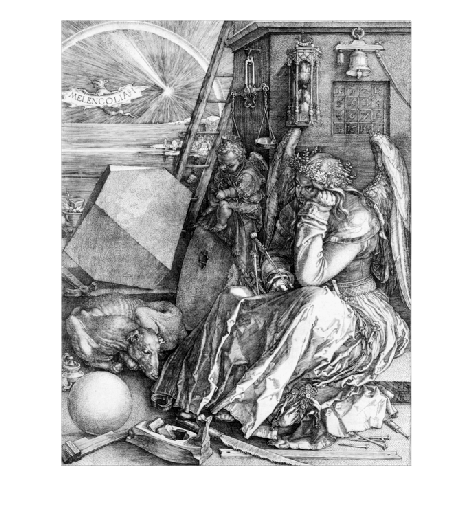

imshow(X,map)

Se reproduce el grabado de  Albrecht Dürer's.

### Leyendo y escribiendo imagenes 

Se pueden leer archivos de imagen estándar (TIFF, JPEG, PNG, etc.) utilizando la función `imread`. El tipo de datos devueltos por `imread` depende del tipo de imagen que se esté leyendo.

También se pueden escribir datos de MATLAB en una variedad de formatos de imagen estándar utilizando la función `imwrite`.

## Impresión de Gráficos

### Descripción general de la Impresión

Puedes imprimir directamente una figura de MATLAB en una impresora conectada a tu computadora o exportar la figura a uno de los formatos de archivo gráfico estándar que MATLAB admite. Hay dos formas de imprimir y exportar figuras:

- Utiliza las opciones GUI de Print, Print Preview o Export Setup en el menú Archivo.

- Utiliza el comando print para imprimir o exportar la figura desde la línea de comandos.

El comando print proporciona un mayor control sobre los controladores y los formatos de archivo. El cuadro de diálogo Print Preview te brinda un mayor control sobre el tamaño de la figura, las proporciones, la ubicación y los encabezados de página.

### Impresión desde el Menú Archivo

Hay dos opciones en el menú Archivo que se relacionan con la impresión:

- La opción Print Preview muestra un cuadro de diálogo que te permite diseñar y dar estilo a las figuras para imprimir mientras visualizas la página de salida y desde el cual puedes imprimir la figura. Incluye opciones que antes formaban parte del cuadro de diálogo Page Setup.

- La opción Print muestra un cuadro de diálogo que te permite elegir una impresora, seleccionar opciones de impresión estándar e imprimir la figura.

Utiliza Print Preview para determinar si la salida impresa es lo que deseas. Haz clic en el botón de ayuda del cuadro de diálogo Print Preview para ver información sobre cómo configurar la página.

### Exportar la Figura a un Archivo Gráfico

La opción Export Setup en el menú Archivo abre una interfaz gráfica de usuario (GUI) que te permite configurar características gráficas, como tamaño de texto, fuente y estilo, para las figuras que guardas como archivos gráficos. El cuadro de diálogo Export Setup te permite definir y aplicar plantillas para personalizar y estandarizar la salida. Después de la configuración, puedes exportar la figura a varios formatos de archivo gráfico estándar, como EPS, PNG y TIFF.

### Uso del Comando Print

El comando print proporciona más flexibilidad en el tipo de salida enviada a la impresora y te permite controlar la impresión desde archivos de función y script. El resultado se puede enviar directamente a tu impresora predeterminada o almacenarse en un archivo de salida especificado. Hay disponibles una amplia variedad de formatos de salida, como TIFF, JPEG y PNG.

Por ejemplo, esta declaración guarda el contenido de la ventana de la figura actual como un gráfico PNG en el archivo llamado magicsquare.png:

`print -dpng magicsquare.png`

Para guardar la misma figura con el mismo tamaño que la figura en la pantalla, utiliza estas declaraciones:

`set(gcf,'PaperPositionMode','auto')`

`print -dpng -r0 magicsquare.png`

Para guardar la misma figura como un archivo TIFF con una resolución de 200 dpi, utiliza el siguiente comando:

`print -dtiff -r200 magicsquare.tiff`

## Trabajar con objetos gráficos

### Objetos gráficos

Los objetos gráficos son elementos básicos utilizados para mostrar gráficos. Estos objetos están organizados en una jerarquía.

Cuando llama a una función de trazado, MATLAB crea el gráfico utilizando varios objetos gráficos, como una ventana de figura, ejes, líneas, texto, etc. Cada objeto tiene un conjunto fijo de propiedades, que puede utilizar para controlar el comportamiento y la apariencia del gráfico.

Por ejemplo, la siguiente declaración crea un gráfico de barras a partir de los datos de la variable `y` y establece propiedades que reflejan el aspecto de las barras:

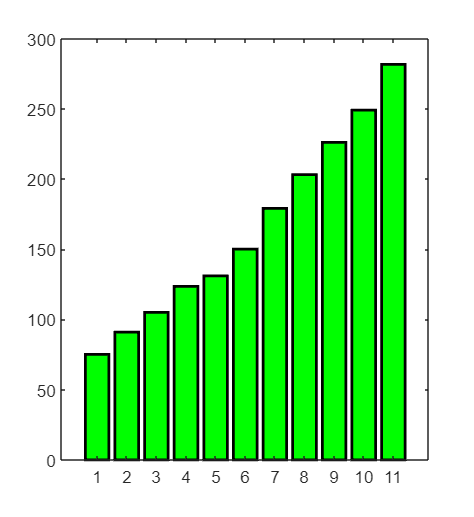

y = [75 91 105 123.5 131 150 179 203 226 249 281.5];
bar(y,'FaceColor','green','EdgeColor','black','LineWidth',1.5)

#### Objetos graficos comunes

Cuando llama a una función para crear un gráfico, MATLAB crea una jerarquía de objetos gráficos. Por ejemplo, llamar a la función `plot` crea los siguientes objetos gráficos:

    • **Figure: **ventana que contiene ejes, barras de herramientas, menús, etc.

    • **Axes: **sistema de coordenadas que contiene el objeto que representa los datos.

    • **Line:** líneas que representan el valor de los datos pasados a la función de trazado.

    •** Text: **etiquetas para marcas de ejes y títulos y anotaciones opcionales.

#### Acceder a las propiedades del objeto

Las funciones de trazado pueden devolver los objetos utilizados para crear el gráfico. Por ejemplo, las siguientes declaraciones crean un gráfico y devuelven el objeto de línea creado por la función de trazado:

x = 1:10;
y = x.^3;
h = plot(x,y);

Utilizamos `h` para establecer las propiedades del objeto de línea. Por ejemplo, establecemos su propiedad `Color`.

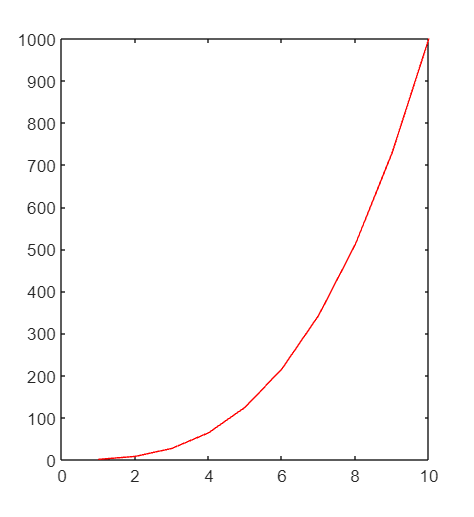

h.Color = 'red';

También se pueden especificar las propiedades de la línea cuando llamamos a la función de trazado.

h = plot(x,y,'Color','red');

Por último, se pueden consultar las propiedades de la línea para ver el valor actual:

h.LineWidth

ans =           0.50


#### Configuración de propiedades de objetos existentes

Para establecer la misma propiedad con el mismo valor en varios objetos, utilizamos la función `set`.

Por ejemplo, las siguientes declaraciones trazan una matriz de 5 por 5 y luego establecen la propiedad `Marker `en cuadrado y la propiedad `MarkerFaceColor `en verde.

y = magic(5);
h = plot(y);
set(h,'Marker','s','MarkerFaceColor','g')

En este caso, `h` es un vector que contiene cinco identificadores, uno para cada una de las cinco líneas del gráfico. La declaración `set `establece las propiedades `Marker `y `MarkerFaceColor `de todas las líneas en el mismo valor.

Para establecer un valor de propiedad en un objeto, indexamos en la matriz de identificadores:

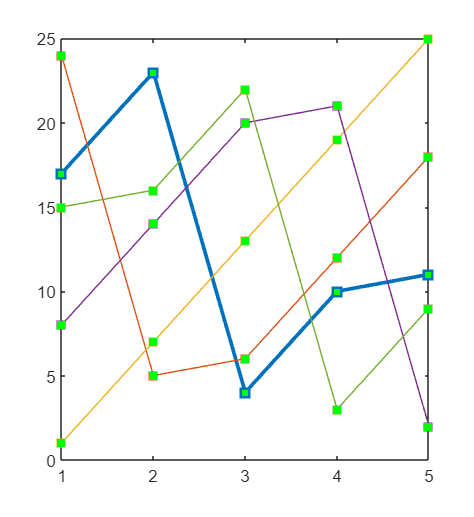

h(1).LineWidth = 2;

#### Establecer múltiples valores de propiedad

Si se desea establecer las propiedades de cada línea en un valor diferente, se pueden usar matrices de celdas para almacenar todos los datos y pasarlos al comando `set`. Por ejemplo, creamos un gráfico y guardamos los identificadores de línea.

figure
y = magic(5);
h = plot(y);

Supongamos que se desea agregar diferentes marcadores a cada línea y colorear la cara del marcador del mismo color que la línea. Debemos definir dos matrices de celdas: una que contenga los nombres de las propiedades y la otra que contenga los valores deseados de las propiedades.

La matriz de celdas `prop_name` contiene dos elementos:

prop_name(1) = {'Marker'};
prop_name(2) = {'MarkerFaceColor'};

La matriz de celdas `prop_values` contiene 10 valores: cinco valores para la propiedad `Marker `y cinco valores para la propiedad `MarkerFaceColor`. Además, se observa que `prop_values` es una matriz de celdas bidimensional. La primera dimensión indica a qué identificador en `h` se aplican los valores y la segunda dimensión indica a qué propiedad se asigna el valor:

prop_values(1,1) = {'s'};
prop_values(1,2) = {h(1).Color};
prop_values(2,1) = {'d'};
prop_values(2,2) = {h(2).Color};
prop_values(3,1) = {'o'};
prop_values(3,2) = {h(3).Color};
prop_values(4,1) = {'p'};
prop_values(4,2) = {h(4).Color};
prop_values(5,1) = {'h'};
prop_values(5,2) = {h(5).Color};

A `MarkerFaceColor` siempre se le asigna el valor del color de la línea correspondiente.

Después de definir las matrices de celdas, llamamos a `set `para especificar los nuevos valores de propiedad:

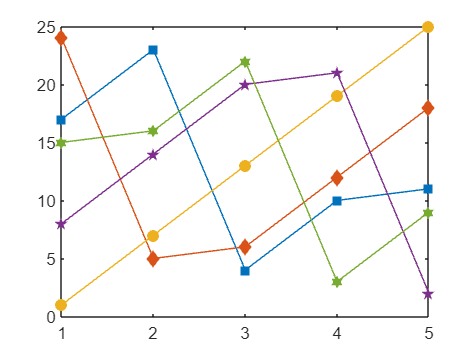

set(h,prop_name,prop_values)

### Funciones para trabajar con objetos

A continuación, se presentan las funciones comúnmente utilizadas cuando se trabaja con objetos:

- `allchild`**:** Encuentra todos los hijos de objetos especificados.

- `ancestor`**:** Encuentra el ancestro del objeto gráfico.

- `copyobj`**: **Copiar objeto gráfico.

- `delete`**:** Eliminar un objeto.

- `findall`**: **Encuentra todos los objetos gráficos (incluidos los identificadores ocultos).

- `findobj`**:** Encuentra los identificadores de objetos que tienen valores de propiedad específicos.

- `gca`**: **Devuelve el identificador de los ejes actuales.

- `gcf`**: **Devuelve el identificador de la figura actual.

- `gco`**:** Devuelve el identificador del objeto actual.

- `get`**:** Consulta los valores de las propiedades de un objeto.

- `ishandle`**:** Verdadero si el valor es un identificador de objeto válido.

- `set`**:** Establecer los valores de las propiedades de un objeto.

### Pasar argumentos

Se pueden definir funciones de trazado especializadas para simplificar la creación de gráficos personalizados. Al definir una función, se pueden pasar argumentos como funciones de trazado de MATLAB.

El siguiente ejemplo muestra una función de MATLAB que evalúa una expresión matemática en el rango especificado en el argumento de entrada `x` y luego traza los resultados. Una segunda llamada a la función `plot` traza el valor medio de los resultados como una línea roja.

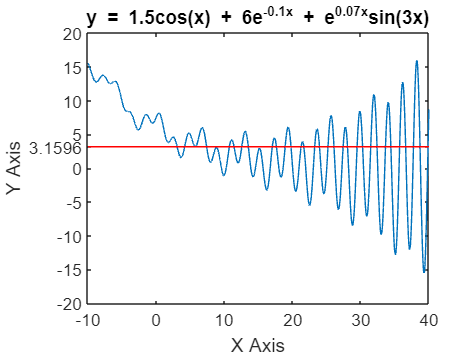

x = -10:.005:40;
plotFunc(x)

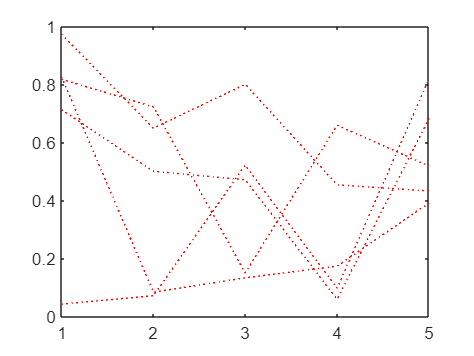

h = findobj('Type','patch');
plot(rand(5),'r:')

h = findobj('Type','line','Color','r','LineStyle',':');
h = findobj(gca,'Type','text','String','\pi/2');

function plotFunc(x)
 y = 1.5*cos(x) + 6*exp(-.1*x) + exp(.07*x).*sin(3*x);
 ym = mean(y);
 hfig = figure('Name','Function and Mean');
 hax = axes('Parent',hfig);
 plot(hax,x,y)
 hold on
 plot(hax,[min(x) max(x)],[ym ym],'Color','red')
 hold off
 ylab = hax.YTick;
 new_ylab = sort([ylab, ym]);
 hax.YTick = new_ylab;
 title ('y = 1.5cos(x) + 6e^{-0.1x} + e^{0.07x}sin(3x)')
 xlabel('X Axis')
 ylabel('Y Axis')
end

Se define un valor para el argumento de entrada y llama a la función:

% x = -10:.005:40;
% plotFunc(x)

#### Encontrar todos los objetos de un determinado tipo

Debido a que todos los objetos tienen una propiedad Tipo que identifica el tipo de objeto, se pueden encontrar los identificadores de todas las apariciones de un tipo particular de objeto. Por ejemplo:

% h = findobj('Type','patch');

### Encontrar Objetos con una Propiedad Particular

Puedes especificar múltiples propiedades para estrechar la búsqueda. Por ejemplo:

% plot(rand(5),'r:')
% h = findobj('Type','line','Color','r','LineStyle',':');

#### Limitar el Alcance de la Búsqueda

Puedes especificar el punto de inicio en la jerarquía de objetos pasando el identificador (handle) de la figura o ejes de inicio como primer argumento. Por ejemplo:

% h = findobj(gca,'Type','text','String','\pi/2');

esto encuentra π/2 solo dentro de los ejes actuales.